# №1 1)

p = [1 4 -2 -14 -3 -18];
%%syms x;
%%poly2sym(p,x)
disp(factor(poly2sym(p)));

$$\left(\begin{array}{cccc} x-2 & x^{2}+1 & x+3 & x+3 \end{array}\right)$$

## №2 1)

syms x;
l = x*exp(-x);
disp(limit(l,x,+inf));

$$0$$

## №2 2)

syms x;
l = tan(x)^(tan(2*x));
disp(limit(l,x,pi/4));

$${\mathrm{e}}^{-1}$$

## №3 5)

syms x;
f = (1/6)*log((x-3)/(x+3));
df = diff(f);
disp(simplify(df));

$$\frac{1}{x^{2}-9}$$

## №4 1)

syms x;
f = sqrt(1-x^2)/x^2;
disp(int(f));

$$-\mathrm{asin}\left(x\right)-\frac{\sqrt{1-x^{2}}}{x}$$

## №4 2)

syms x;
f = 1/(sin(x))^3;
disp(int(f));

$$\frac{\log\left(\tan\left(\frac{x}{2}\right)\right)}{2}-\frac{\cos\left(x\right)}{2\,{\sin\left(x\right)}^{2}}$$

## № 5 1)

syms n; syms m;
s = symsum(1/(n^2),n,1,m);
disp(limit(s,m,inf));

$$s = \sum_{n=1}^{m}\frac{{\left(x-3\right)}^{2\,n}}{\sqrt{n}}$$

## №6 2)

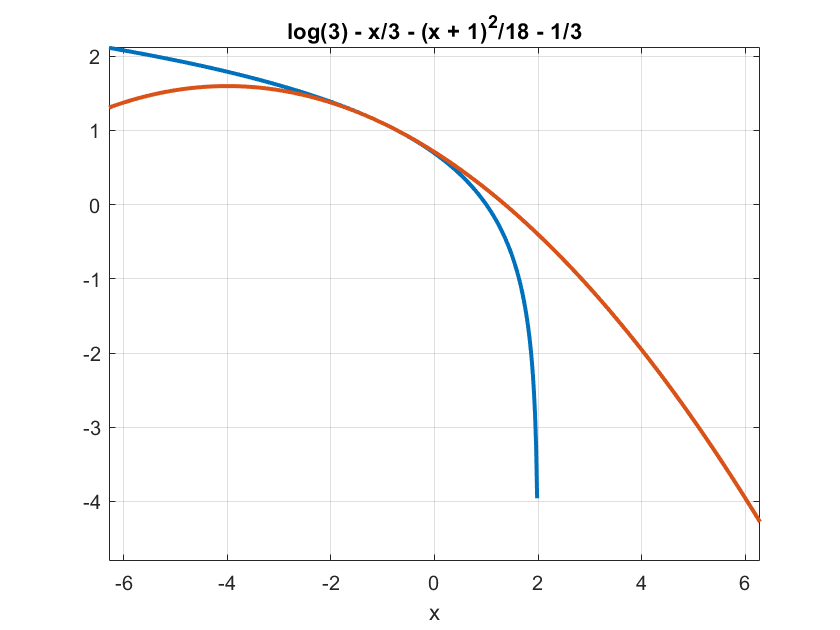

syms x;
a = -1; n = 3;
f = log(2-x);
t = taylor(f, x, a,'Order',n);
x = -10:0.1:10;
g(1) = ezplot(f);
hold on; grid on;
g(2) = ezplot(t);
set(g, 'LineWidth', 2);
hold off;

disp(t);

$$\log\left(3\right)-\frac{x}{3}-\frac{{\left(x+1\right)}^{2}}{18}-\frac{1}{3}$$

## №7

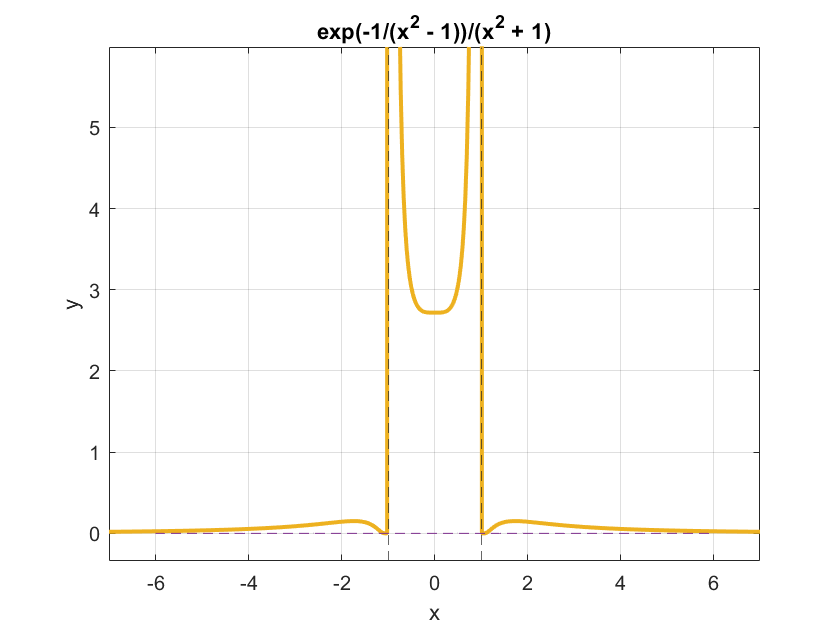

syms x;
f = exp(1/(1-x^2))/(1+x^2);
g = ezplot(f,-7,7);
set(g,'LineWidth',2);
hold on; grid on; ylabel('y');
k = limit(f/x,x,-inf);
b = limit(f-k*x,x,-inf);
y_n = k*x+b;
x_v = [-1 0 1];
x_r = roots(x_v);
v_as(1) = limit(f,x,x_r(1),'right');
v_as(2) = limit(f,x,x_r(2),'right');
v_as(3) = limit(f,x,x_r(1),'left');
v_as(4) = limit(f,x,x_r(2),'left');
%%disp(v_as);
n = 1;
for i = 1:4
    if (v_as(i) ~= inf) 
        y(n) = v_as(i); 
        n = n+1;
    end
end
%%disp(y);
x_plot = -6:0.1:6;
y_n = y_n.*x_plot;
plot(x_plot,y_n,'--');
xline(x_r(1),'--');
xline(x_r(2),'--');

xlim([-7.0 7.0])
ylim([-0.34 5.99])
hold off;